# synchronization analysis

% load data 
load('Norm1HighBase_reg_segmented.mat')

tsPass = normalize(double(cell2mat({result.segmves.tsPass}.'))');
numVes = size(tsPass,2);
pairs = nchoosek(1:numVes,2);
numPairs = size(pairs,1);
syncVals = zeros(numPairs,1);

for i = 1:numPairs
    ts1 = tsPass(:,pairs(i,1));
    ts2 = tsPass(:,pairs(i,2));
    [wt1,f] = cwt(ts1,1,FrequencyLimits = [0.015 0.04]);
    wt1 = abs(wt1).^2;
    [M,I] = max(wt1);
    peaks1 = f(I);
    
    [wt2,f] = cwt(ts2,1,FrequencyLimits = [0.015 0.04]);
    wt2 = abs(wt2).^2;
    [M,I] = max(wt2);
    peaks2 = f(I);
    matches = single(peaks1==peaks2);
    intervals = single(~matches);
    [~,locs,widths,~]=findpeaks(intervals,'MaxPeakWidth',26);
    for ii = 1:length(locs)
    idx = locs(ii);
    len = widths(ii);
    intervals(idx:idx+len-1) = 0;
    end
    matches = single(~intervals);
    [~,~,w,~]=findpeaks(matches,'MinPeakWidth',100);
    syncVals(i) = sum(w)/length(peaks1);
end 
syncVals = syncVals*100;

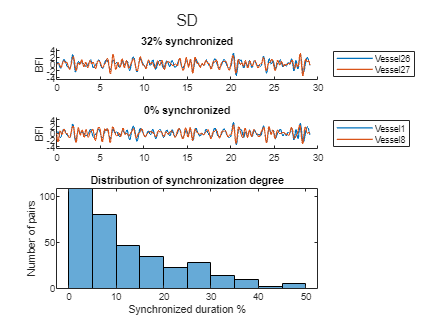

figure
t = tiledlayout(4,1);
nexttile
%[M,i] = max(syncVals);
M = syncVals(25);
M = round(M);
ves1 = tsPass(:,pairs(25,1));
ves2 = tsPass(:,pairs(25,2));
A = pairs(i,1);
B = pairs(i,2);
time = linspace(0,length(ves1)/60,length(ves1));
plot(time,ves1,'LineWidth',1)
hold on 
plot(time,ves2,'LineWidth',1)
hold off 
legend(['Vessel',num2str(A)], ['Vessel',num2str(B)], 'Location', 'eastoutside')
ylim([-4.5 4.5])
ylabel('BFI');
title([num2str(M),'% synchronized'])
ax = gca;
ax.Box = 'off';

nexttile
[M,i] = min(syncVals);
M = round(M);
ves1 = tsPass(:,pairs(i,1));
ves2 = tsPass(:,pairs(i,2));
A = pairs(i,1);
B = pairs(i,2);
time = linspace(0,length(ves1)/60,length(ves1));
plot(time,ves1,'LineWidth',1)
hold on 
plot(time,ves2,'LineWidth',1)
hold off 
legend(['Vessel',num2str(A)], ['Vessel',num2str(B)], 'Location', 'eastoutside')
ylim([-4.5 4.5])
ylabel('BFI');
title([num2str(M),'% synchronized'])
ax = gca;
ax.Box = 'off';

nexttile([2 1])

histogram(syncVals);
xlabel('Synchronized duration %');
ylabel('Number of pairs');
title('Distribution of synchronization degree')

title(t,'SD')

fNames{1} ='Norm1HighBase_reg_segmented.mat'; 
fNames{2} ='Norm2HighBase_reg_segmented.mat'; 
fNames{3} ='Norm3HighBase_reg_segmented.mat'; 
fNames{4} ='Norm4HighBase_reg_segmented.mat'; 
fNames{5} ='Norm5HighBase_reg_segmented.mat'; 
fNames{6} ='Norm6HighBase_reg_segmented.mat'; 
fNames{7} ='Norm7HighBase_reg_segmented.mat'; 
fNames{8} ='Norm9HighBase_reg_segmented.mat'; 
fNames{9} ='Norm10HighBase_reg_segmented.mat';

sdSync = [];

for file = 1:length(fNames)
    load(fNames{file})
    tsPass = normalize(double(cell2mat({result.segmves.tsPass}.'))');
    numVes = size(tsPass,2);
    pairs = nchoosek(1:numVes,2);
    numPairs = size(pairs,1);
    syncVals = zeros(numPairs,1);
    
    for i = 1:numPairs
        ts1 = tsPass(:,pairs(i,1));
        ts2 = tsPass(:,pairs(i,2));
        [wt1,f] = cwt(ts1,1,FrequencyLimits = [0.015 0.04]);
        wt1 = abs(wt1).^2;
        [M,I] = max(wt1);
        peaks1 = f(I);
        
        [wt2,f] = cwt(ts2,1,FrequencyLimits = [0.015 0.04]);
        wt2 = abs(wt2).^2;
        [M,I] = max(wt2);
        peaks2 = f(I);
        % find longest subarray with consecutive values  
        matches = single(peaks1==peaks2);
        intervals = single(~matches);
        % remove any intervals less than 26 seconds 
        [~,locs,widths,~]=findpeaks(intervals,'MaxPeakWidth',26);
            for ii = 1:length(locs)
            idx = locs(ii);
            len = widths(ii);
            intervals(idx:idx+len-1) = 0;
            end
        matches = single(~intervals);
        [~,~,w,~]=findpeaks(matches,'MinPeakWidth',100);
        %[~,~,w,~]=findpeaks(matches);
        syncVals(i) = sum(w)/length(peaks1);
    end 
    syncVals = syncVals*100;
    sdSync = [sdSync;syncVals];
end 

fNames{1} ='SHR1HighBase_reg_segmented.mat'; 
fNames{2} ='SHR2HighBase_reg_segmented.mat'; 
fNames{3} ='SHR3HighBase_reg_segmented.mat'; 
fNames{4} ='SHR4HighBase_reg_segmented.mat'; 
fNames{5} ='SHR5HighBase_reg_segmented.mat'; 
fNames{6} ='SHR6HighBase_reg_segmented.mat'; 
fNames{7} ='SHR7HighBase_reg_segmented.mat'; 
fNames{8} ='SHR8HighBase_reg_segmented.mat'; 
fNames{9} ='SHR9HighBase_reg_segmented.mat';

shSync = [];

for file = 1:length(fNames)
    load(fNames{file})
    tsPass = normalize(double(cell2mat({result.segmves.tsPass}.'))');
    numVes = size(tsPass,2);
    pairs = nchoosek(1:numVes,2);
    numPairs = size(pairs,1);
    syncVals = zeros(numPairs,1);
    
    for i = 1:numPairs
        ts1 = tsPass(:,pairs(i,1));
        ts2 = tsPass(:,pairs(i,2));
        [wt1,f] = cwt(ts1,1,FrequencyLimits = [0.015 0.04]);
        wt1 = abs(wt1).^2;
        [M,I] = max(wt1);
        peaks1 = f(I);
        
        [wt2,f] = cwt(ts2,1,FrequencyLimits = [0.015 0.04]);
        wt2 = abs(wt2).^2;
        [M,I] = max(wt2);
        peaks2 = f(I);
        matches = single(peaks1==peaks2);
        intervals = single(~matches);
        [~,locs,widths,~]=findpeaks(intervals,'MaxPeakWidth',26);
            for ii = 1:length(locs)
            idx = locs(ii);
            len = widths(ii);
            intervals(idx:idx+len-1) = 0;
            end
        matches = single(~intervals);
        [~,~,w,~]=findpeaks(matches,'MinPeakWidth',100);
        %[~,~,w,~]=findpeaks(matches);
        syncVals(i) = sum(w)/length(peaks1);
    end 
    syncVals = syncVals*100;
    shSync = [shSync;syncVals];
end


## stats 

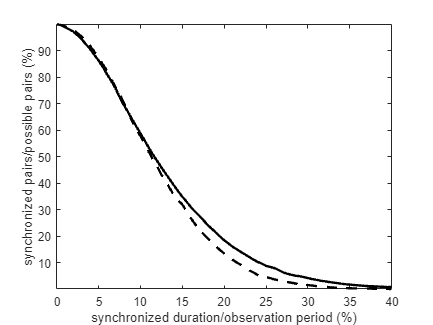

% of pairs synchronized for +20% of observation period, normalized by the
% total number of vessel pairs observed 
% bins for 2.5 % duration to 100% of the duration 
figure
dois = 0:0.5:100; % vector in percentage 
probSD = zeros(length(dois),1);
probSH = zeros(length(dois),1);
for i = 1:length(dois)
    probSD(i) = sum(sdSync>dois(i))/length(sdSync);
    probSH(i) = sum(shSync>dois(i))/length(shSync);
end 
probSD = probSD*100;
probSH = probSH*100;
plot(dois,probSD,'LineWidth',2,'Color','k')
hold on 
plot(dois,probSH,'LineWidth',2,'Color','k','LineStyle','--')
hold off
%xline(5,'--',{'Threshold'});
axis tight
ylabel('synchronized pairs/possible pairs (%)')
xlabel('synchronized duration/observation period (%)')
 xlim([0 40])

% ylim([0 50])
%legend('SD','SH')